% -----------------------------------------------------------------
% Left wheel forward
% -----------------------------------------------------------------

% -------------------------------
% 50% PWM speed
% -------------------------------

% TRUE: Degrees (time turned on as a proxy for displacement- based on seconds given to rotate)
raw_x = [207;   % 1s
         687;   % 2s
         1165;  % 3s
         1938;  % 5s
         4460  % 10s
         ]  

raw_x =          207
         687
        1165
        1938
        4460


% MEASURED: Encoder count (Falling edge, channel A + B: Expect 2240 CPR)
raw_y = [1280, 1274, 1276, 1282, 1280, 1292, 1280, 1284, 1280, 1276; 
         4273, 4253, 4264, 4275, 4281, 4267, 4270, 4268, 4271, 4254; 
         7262, 7257, 7328, 7241, 7250, 7272, 7244, 7239, 7228, 7247;
         13210, 13168, 13180, 13186, 13182, 13176, 13202, 13199, 13206, 13226;
         27748, 27727, 27905, 27899, 27792, 28436, 28695, 28026, 27863, 27837]

raw_y =         1280        1274        1276        1282        1280        1292        1280        1284        1280        1276
        4273        4253        4264        4275        4281        4267        4270        4268        4271        4254
        7262        7257        7328        7241        7250        7272        7244        7239        7228        7247
       13210       13168       13180       13186       13182       13176       13202       13199       13206       13226
       27748       27727       27905       27899       27792       28436       28695       28026       27863       27837






% Degrees -> Angular displacement (radians)
x = deg2rad(raw_x)

x =     3.6128
   11.9904
   20.3331
   33.8245
   77.8417


% Encoder count -> Angular displacement (radians) by assuming 2240 CPR
y = (raw_y./2240).*2*pi

y =     3.5904    3.5736    3.5792    3.5960    3.5904    3.6241    3.5904    3.6016    3.5904    3.5792
   11.9857   11.9296   11.9605   11.9913   12.0082   11.9689   11.9773   11.9717   11.9801   11.9324
   20.3699   20.3558   20.5550   20.3110   20.3362   20.3979   20.3194   20.3053   20.2745   20.3278
   37.0540   36.9362   36.9698   36.9866   36.9754   36.9586   37.0315   37.0231   37.0427   37.0988
   77.8330   77.7741   78.2733   78.2565   77.9564   79.7628   80.4893   78.6127   78.1555   78.0826


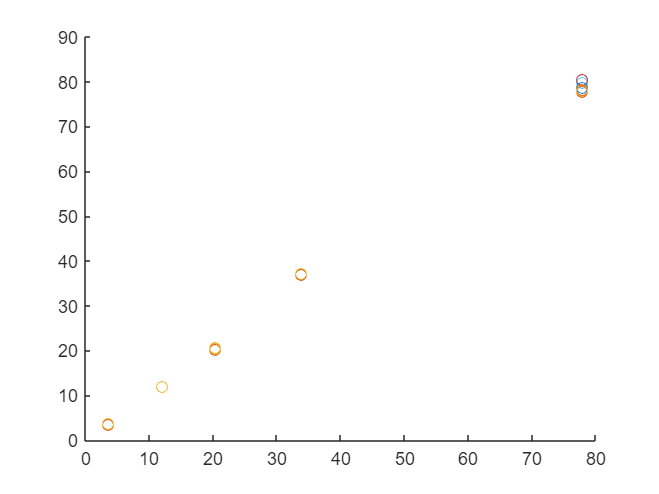


scatter(x, y)

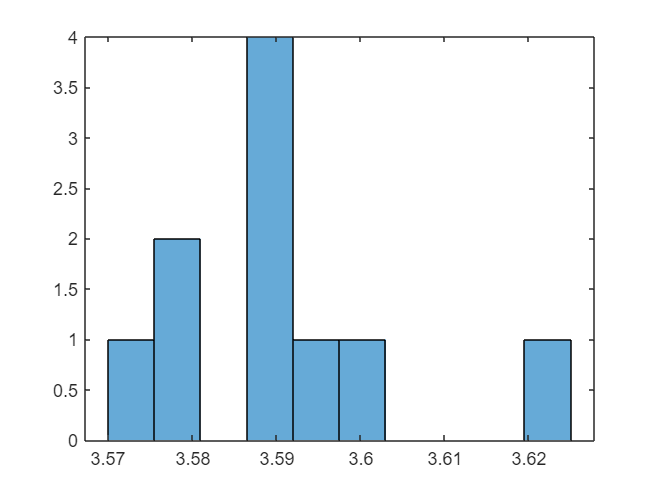

histogram(y(1,:), 10)

[muHat,sigmaHat,muCI,sigmaCI] = normfit(y(:,1),0.01)

Unrecognized function or variable 'normfit'.

% -----------------------------------------------------------------
% Right wheel forward
% -----------------------------------------------------------------

% -------------------------------
% 50% PWM speed
% -------------------------------

% TRUE: Degrees
raw_x = [210;   % 1s
         698;   % 2s
         1190;  % 3s
         2165;  % 5s
         4567  % 10s
         ]
% MEASURED: Encoder count (channel A + B)
raw_y = [1317, 1320, 1321, 1310, 1310, 1314, 1312, 1308, 1309, 1296; 
         4352, 4342, 4336, 4353, 4346, 4366, 4348, 4351, 4375, 4461; 
         7532, 7565, 7488, 7432, 7423, 7437, 7416, 7402, 7393, 7397;
         13581, 13469, 13454, 13463, 13438, 13444, 13487, 13469, 13511, 13450;
         28469, 28428, 28555, 28590, 28524, 29013, 29366, 28767, 28557, 28595]

% Degrees -> Angular displacement (radians)
x = deg2rad(raw_x)
% Encoder count -> Angular displacement (radians)
y = (raw_y./2240).*2*pi

scatter(x, y)